# rojTop view plot

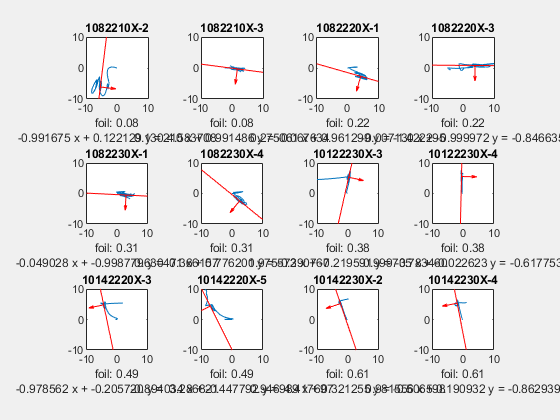

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
        % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2); 
        % draw arrow for view point
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        ax(i) = subplot(3,4,i);
        plot(x,y);
        hold on;
        plot(xline,yline,'-r');
        hold on;
        quiver(p(1),p(2),-5/AntiSlope/LengthUnit,- 5/LengthUnit,'AutoScale','off','MaxHeadSize',2,'color','r');
        axis equal;
        title(FileName{i});
        xlim([-10, 10]);
        ylim([-10, 10]);
        xlabel({['foil: ', num2str(foil(i))]; sprintf('%f x + %f y = % f', a, b ,d)})
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        save(path,'traj3D','Plane');
    end
end
savefig('10_oil_TopViewTraj.fig')

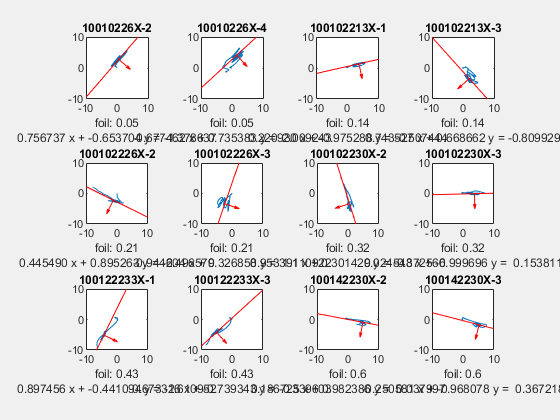

figure('visible','on');
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
       % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2); 
        % draw arrow for view point
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        subplot(3,4,i-12);
        plot(x,y);
        hold on;
        plot(xline,yline,'-r');
        hold on;
        quiver(p(1),p(2),-5/AntiSlope/LengthUnit,- 5/LengthUnit,'AutoScale','off','MaxHeadSize',2,'color','r');
        axis equal;
        title(FileName{i});
        xlim([-10, 10]);
        ylim([-10, 10]);
        xlabel({['foil: ', num2str(foil(i))]; sprintf('%f x + %f y = % f', a, b ,d)})
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        save(path,'traj3D','Plane');
    end
end
savefig('100_oil_TopViewTraj.fig')

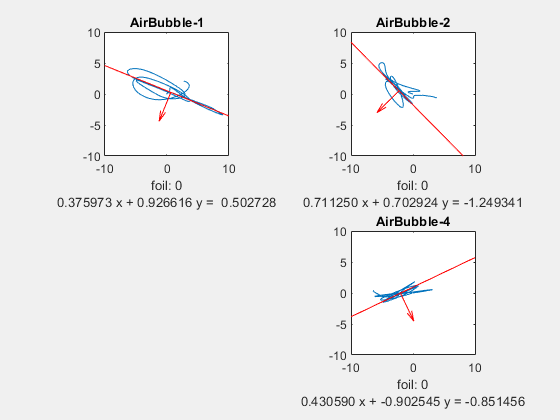

figure('visible','on');
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
         % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2); 
        % draw arrow for view point
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        subplot(2,2,i-24);
        plot(x,y);
        hold on;
        plot(xline,yline,'-r');
        hold on;
        quiver(p(1),p(2),-5/AntiSlope/LengthUnit,- 5/LengthUnit,'AutoScale','off','MaxHeadSize',2,'color','r');
        axis equal;
        title(FileName{i});
        xlim([-10, 10]);
        ylim([-10, 10]);
        xlabel({['foil: ', num2str(foil(i))]; sprintf('%f x + %f y = % f', a, b ,d)})
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        save(path,'traj3D','Plane');
    end
end
savefig('Air_TopViewTraj.fig')

figure('visible','on');
clf;
for i = 29:35
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
         % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2); 
        % draw arrow for view point
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        subplot(3,3,i-28);
        plot(x,y);
        hold on;
        plot(xline,yline,'-r');
        hold on;
        quiver(p(1),p(2),-5/AntiSlope/LengthUnit,- 5/LengthUnit,'AutoScale','off','MaxHeadSize',2,'color','r');
        axis equal;
        title(FileName{i});
        xlim([-10, 10]);
        ylim([-10, 10]);
        xlabel({['foil: ', num2str(foil(i))]; sprintf('%f x + %f y = % f', a, b ,d)})
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        save(path,'traj3D','Plane');
    end
end
savefig('SevenMoreCaseTopViewTraj.fig')

clear all
DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'

DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'

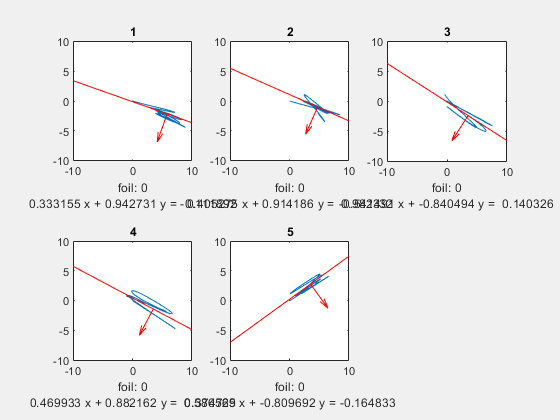

figure('visible','on');
clf;
for i = 1:5
    path = [DataPath, num2str(i), '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
        % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2); 
        % draw arrow for view point
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        ax(i) = subplot(2,3,i);
        plot(x,y);
        hold on;
        plot(xline,yline,'-r');
        hold on;
        quiver(p(1),p(2),-5/AntiSlope/LengthUnit,- 5/LengthUnit,'AutoScale','off','MaxHeadSize',2,'color','r');
        axis equal;
        title(num2str(i));
        xlim([-10, 10]);
        ylim([-10, 10]);
        xlabel({['foil: ', num2str(0)]; sprintf('%f x + %f y = % f', a, b ,d)})
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        save(path,'traj3D','Plane');
    end
end
savefig('Air_New_TopViewTraj.fig')

## Sideview projection plot

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane;
        a = Plane(1); b = Plane(2); c = Plane(3);
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        unitV = [-1/AntiSlope/LengthUnit, - 1/LengthUnit];
        yV = [0, -1];
        theta = rad2deg(acos(dot(unitV,yV)/norm(unitV)));
        if -1/AntiSlope/LengthUnit < 0
            theta = -theta
        end
        ax(i) = subplot(3,4,i);
        plot3(traj3D(:,1),traj3D(:,2),traj3D(:,3),'Color','r','LineWidth',1);
        xlim([-10, 10]);
        ylim([-10, 10]);
        zlim([0, 200]);
        view(theta, 0);
        title(FileName{i});
    end
end

theta = -7.4817

theta = -15.9677

theta = -0.4085

theta = -2.8103

theta = -39.0853

theta = -78.1278

theta = -63.3952

theta = -71.2611

theta = -78.9923

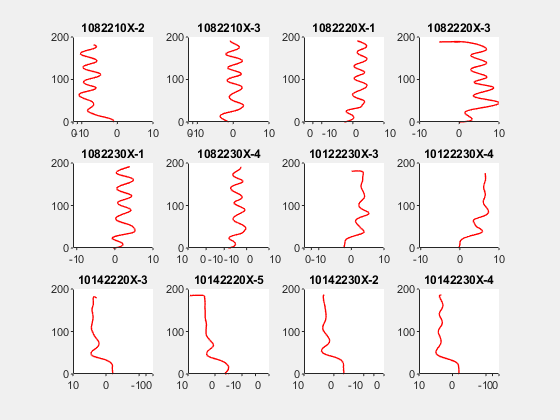

savefig('BestPlaneView10Oil.fig')

figure('visible','on');
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane;
        a = Plane(1); b = Plane(2); c = Plane(3);
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        unitV = [-1/AntiSlope/LengthUnit, - 1/LengthUnit];
        yV = [0, -1];
        theta = rad2deg(acos(dot(unitV,yV)/norm(unitV)));
        if -1/AntiSlope/LengthUnit < 0
            theta = -theta
        end
        ax(i) = subplot(3,4,i - 12);
        plot3(traj3D(:,1),traj3D(:,2),traj3D(:,3),'Color','r','LineWidth',1);
        xlim([-10, 10]);
        ylim([-10, 10]);
        zlim([0, 200]);
        view(theta, 0);
        title(FileName{i});
    end
end

theta = -48.0346

theta = -26.4553

theta = -72.4549

theta = -10.7620

theta = -14.5122

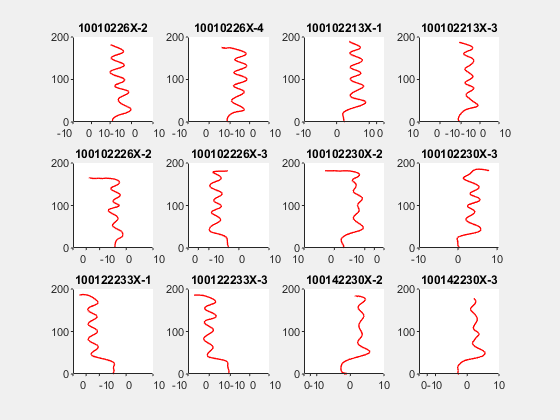

savefig('BestPlaneView100Oil.fig')

figure('visible','on');
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane;
        a = Plane(1); b = Plane(2); c = Plane(3);
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        unitV = [-1/AntiSlope/LengthUnit, - 1/LengthUnit];
        yV = [0, -1];
        theta = rad2deg(acos(dot(unitV,yV)/norm(unitV)));
        if -1/AntiSlope/LengthUnit < 0
            theta = -theta
        end
        ax(i) = subplot(2,2,i - 24);
        plot3(traj3D(:,1),traj3D(:,2),traj3D(:,3),'Color','r','LineWidth',1);
        xlim([-10, 10]);
        ylim([-10, 10]);
        zlim([0, 200]);
        view(theta, 0);
        title(FileName{i});
    end
end

theta = -22.0848

theta = -45.3373

savefig('BestPlaneViewAir.fig')

figure('visible','on');
clf;
for i = 29:35
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane;
        a = Plane(1); b = Plane(2); c = Plane(3);
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        unitV = [-1/AntiSlope/LengthUnit, - 1/LengthUnit];
        yV = [0, -1];
        theta = rad2deg(acos(dot(unitV,yV)/norm(unitV)));
        if -1/AntiSlope/LengthUnit < 0
            theta = -theta
        end
        ax(i) = subplot(3,3,i - 28);
        plot3(traj3D(:,1),traj3D(:,2),traj3D(:,3),'Color','r','LineWidth',1);
        xlim([-10, 10]);
        ylim([-10, 10]);
        zlim([0, 200]);
        view(theta, 0);
        title(FileName{i});
    end
end

theta = -30.9093

theta = -86.1878

theta = -78.3024

theta = -24.1256

theta = -23.9165

theta = -16.0333

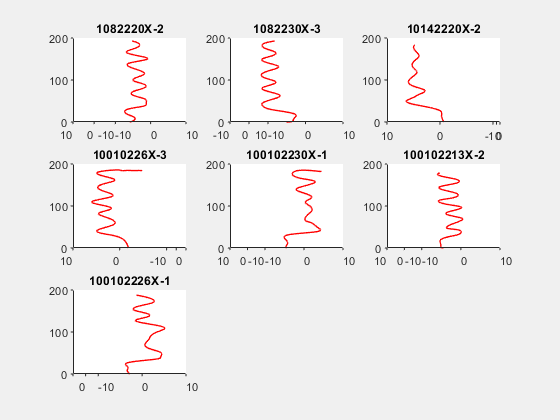

savefig('SevenMoreCaseBestPlaneView.fig')

clear all
DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'

DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'

figure('visible','on');
clf;
for i = 1:5
    path = [DataPath, num2str(i), '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane;
        a = Plane(1); b = Plane(2); c = Plane(3);
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        unitV = [-1/AntiSlope/LengthUnit, - 1/LengthUnit];
        yV = [0, -1];
        theta = rad2deg(acos(dot(unitV,yV)/norm(unitV)));
        if -1/AntiSlope/LengthUnit < 0
            theta = -theta
        end
        ax(i) = subplot(2,3,i);
        plot3(traj3D(:,1),traj3D(:,2),traj3D(:,3),'Color','r','LineWidth',1);
        xlim([-10, 10]);
        ylim([-10, 10]);
        zlim([0, 200]);
        view(theta, 0);
        title(num2str(i));
    end
end

theta = -19.4631

theta = -23.9086

theta = -32.7918

theta = -28.0445

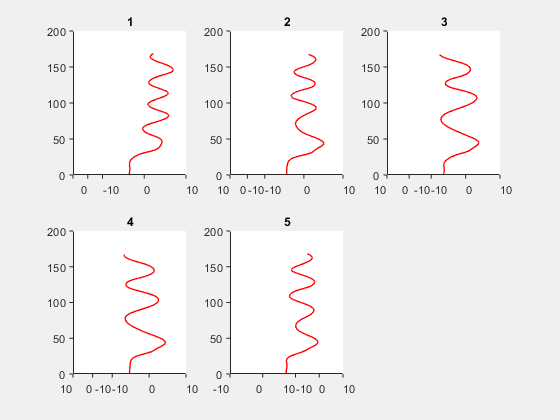

savefig('BestPlaneViewAirNew.fig')

## Velocity analysis

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        subplot(3,4,i);
        plot(xplot,u);
        hold on;
        plot(xplot,v);
        hold on;
        plot(xplot,w);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-100, 300]);
        xlabel('t (ms)');
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('u','v','w','speed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('Velocity10oil.fig')
saveas(gcf,'Velocity10oil.png')

Error using checkArgsForHandleToPrint
Handle input argument contains nonhandle values.

Error in checkArgsForHandleToPrint

Error in print>LocalCreatePrintJob (line 101)
handles = checkArgsForHandleToPrint(0, varargin{:});

Error in print (line 38)
[pj, inputargs] = LocalCreatePrintJob(varargin{:});

Error in 

figure('visible','on');
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        subplot(3,4,i-12);
        plot(xplot,u);
        hold on;
        plot(xplot,v);
        hold on;
        plot(xplot,w);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-100, 300]);
        xlabel('t (ms)');
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('u','v','w','speed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('Velocity100oil.fig')
saveas(gcf,'Velocity100oil.png')
figure('visible','on');
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        subplot(2,2,i-24);
        plot(xplot,u);
        hold on;
        plot(xplot,v);
        hold on;
        plot(xplot,w);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel('t (ms)');
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('u','v','w','speed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('VelocityAir.fig')
saveas(gcf,'VelocityAir.png')

figure('visible','on');
clf;
for i = 29:35
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        subplot(3,3,i-28);
        plot(xplot,u);
        hold on;
        plot(xplot,v);
        hold on;
        plot(xplot,w);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel('t (ms)');
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('u','v','w','speed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('sevenMoreCaseVelocity.fig')
saveas(gcf,'sevenMoreCaseVelocity.png')

clear all
DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'
figure('visible','on');
clf;
for i = 1:5
    path = [DataPath, num2str(i), '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        subplot(2,3,i);
        plot(xplot,u);
        hold on;
        plot(xplot,v);
        hold on;
        plot(xplot,w);
        hold on;
        plot(xplot,speed);
        hold off;
        title(num2str(i));
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel('t (ms)');
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('u','v','w','speed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('VelocityAirNew.fig')
saveas(gcf,'VelocityAirNew.png')

## Transverse speed analysis

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,4,i);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-100, 300]);
        xlabel(['t (ms) ', 'foil: ', num2str(foil(i))]);
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('TransverseSpeed10oil.fig')

figure('visible','on');
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,4,i-12);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-100, 300]);
        xlabel(['t (ms) ', 'foil: ', num2str(foil(i))]);
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('TransverseSpeed100oil.fig')

figure('visible','on');
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(2,2,i-24);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel(['t (ms) ', 'foil: ', num2str(foil(i))]);
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('TransverseSpeedAir.fig')

figure('visible','on');
clf;
for i = 29:35
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,3,i-28);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel(['t (ms) ', 'foil: ', num2str(foil(i))]);
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('sevenMoreCaseTransverseSpeed.fig')
saveas(gcf,'sevenMoreCaseTransverseSpeed.png')

clear all
DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'
figure('visible','on');
clf;
for i = 1:5
    path = [DataPath, num2str(i), '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(2,3,i);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(num2str(i));
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel(['t (ms) ', 'foil: ', num2str(0)]);
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('TransverseSpeedAirNew.fig')

## Vertical Velocity

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
SpeedTableVertical = [];
SpeedTableTransverse = [];
figure('visible','on');
clf;
foilPlot = []; W = []; error = []; totalSpeed = []; totalError = [];
for i = 1:2:12
    path1 = [ReadingPath, FileName{i}, '.mat'];
    path2 = [ReadingPath, FileName{i + 1}, '.mat'];
    if isfile(path1)
        data = load(path1);
        traj3D = data.traj3D;
        z = traj3D(:,3);
        minID = min(find(z > 80));
        maxID = max(find(z < 150));
        w = traj3D(minID:maxID,6);
        u = traj3D(minID:maxID,4);
        v = traj3D(minID:maxID,5);
        Total = sqrt(w.^2 + u.^2 + v.^2);
        meanTotal1 = mean(Total);
        u1 = mean(w);
        k1 = mean(sqrt(u.^2 + v.^2));
        SpeedTableVertical = [SpeedTableVertical; u1];
        SpeedTableTransverse = [SpeedTableTransverse; k1];
    end
    if isfile(path2)
        data = load(path2);
        traj3D = data.traj3D;
        z = traj3D(:,3);
        minID = min(find(z > 80));
        maxID = max(find(z < 150));
        w = traj3D(minID:maxID,6);
        u = traj3D(minID:maxID,4);
        v = traj3D(minID:maxID,5);
        Total = sqrt(w.^2 + u.^2 + v.^2);
        meanTotal2 = mean(Total);
        u2 = mean(w);
        k2 = mean(sqrt(u.^2 + v.^2));
        SpeedTableVertical = [SpeedTableVertical; u2];
        SpeedTableTransverse = [SpeedTableTransverse; k2];
    end
    uCenter = (u1 + u2)/2;
    range = abs(u1 - u2);  
    foilPlot = [foilPlot, foil(i)];
    W = [W, uCenter];
    error = [error, range];
    tCenter = (meanTotal1 + meanTotal2)/2;
    tRange = abs(meanTotal2 - meanTotal1);
    totalSpeed = [totalSpeed, tCenter];
    totalError = [totalError, tRange];
end
errorbar(foilPlot,W,error);
hold on;
errorbar(foilPlot,totalSpeed, totalError);
hold off;
xlabel('oil fraction');
ylabel('Vertical Speed (mm/s)');
ylim([150,250]); xlim([0, 0.7]);
savefig('VerticalV10Oil.fig')

figure('visible','on');
clf;
foilPlot = []; W = []; error = [];totalSpeed = []; totalError = [];
for i = 13:2:24
    path1 = [ReadingPath, FileName{i}, '.mat'];
    path2 = [ReadingPath, FileName{i + 1}, '.mat'];
    if isfile(path1)
        data = load(path1);
        traj3D = data.traj3D;
        z = traj3D(:,3);
        minID = min(find(z > 80));
        maxID = max(find(z < 150));
        w = traj3D(minID:maxID,6);
        u = traj3D(minID:maxID,4);
        v = traj3D(minID:maxID,5);
        Total = sqrt(w.^2 + u.^2 + v.^2);
        meanTotal1 = mean(Total);
        u1 = mean(w);
        k1 = mean(sqrt(u.^2 + v.^2));
        SpeedTableVertical = [SpeedTableVertical; u1];
        SpeedTableTransverse = [SpeedTableTransverse; k1];
    end
    if isfile(path2)
        data = load(path2);
        traj3D = data.traj3D;
        z = traj3D(:,3);
        minID = min(find(z > 80));
        maxID = max(find(z < 150));
        w = traj3D(minID:maxID,6);
        u = traj3D(minID:maxID,4);
        v = traj3D(minID:maxID,5);
        Total = sqrt(w.^2 + u.^2 + v.^2);
        meanTotal2 = mean(Total);
        u2 = mean(w);
        k2 = mean(sqrt(u.^2 + v.^2));
        SpeedTableVertical = [SpeedTableVertical; u2];
        SpeedTableTransverse = [SpeedTableTransverse; k2];
    end
    uCenter = (u1 + u2)/2;
    range = abs(u1 - u2);  
    foilPlot = [foilPlot, foil(i)];
    W = [W, uCenter];
    error = [error, range];
    tCenter = (meanTotal1 + meanTotal2)/2;
    tRange = abs(meanTotal2 - meanTotal1);
    totalSpeed = [totalSpeed, tCenter];
    totalError = [totalError, tRange];
end
errorbar(foilPlot,W,error);
hold on;
errorbar(foilPlot,totalSpeed, totalError);
hold off;
xlabel('oil fraction');
ylabel('Vertical Speed (mm/s)');
ylim([150,250]); xlim([0, 0.7]);
savefig('VerticalV100Oil.fig')

figure('visible','on');
clf;
foilPlot = []; W = []; error = [];totalSpeed = []; totalError = [];
for i = 29:35
    path1 = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path1)
        data = load(path1);
        traj3D = data.traj3D;
        z = traj3D(:,3);
        minID = min(find(z > 80));
        maxID = max(find(z < 150));
        w = traj3D(minID:maxID,6);
        u = traj3D(minID:maxID,4);
        v = traj3D(minID:maxID,5);
        Total = sqrt(w.^2 + u.^2 + v.^2);
        meanTotal1 = mean(Total);
        u1 = mean(w);
        k1 = mean(sqrt(u.^2 + v.^2));
        SpeedTableVertical = [SpeedTableVertical; u1];
        SpeedTableTransverse = [SpeedTableTransverse; k1];
    end
end


clear all
DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'
figure('visible','on');
clf;
SpeedTableVertical = [];
SpeedTableTransverse = [];
for i = 1:5
    path = [DataPath, num2str(i), '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        z = traj3D(:,3)
        minID = min(find(z > 80));
        maxID = max(find(z < 150));
        w = traj3D(minID:maxID,6);
        u = traj3D(minID:maxID,4);
        v = traj3D(minID:maxID,5);
        Total = sqrt(w.^2 + u.^2 + v.^2);
        meanTotal2 = mean(Total);
        u2 = mean(w);
        k2 = mean(sqrt(u.^2 + v.^2));
        SpeedTableVertical = [SpeedTableVertical; u2];
        SpeedTableTransverse = [SpeedTableTransverse; k2];
    end
end


## Wavelet

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
freq10 = [];
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,4,i);
        %cwt(Tspeed,200);
        [ift,t] = instfreq(Tspeed,200);
        instfreq(Tspeed,200);
        freq = mean(ift);
        freq10 = [freq10, freq];
        xlabel({['Overall freq: ', num2str(freq)],['oil fraction: ', num2str(foil(i))]});
    end
end
savefig('freq10oil.fig')
figure('visible','on');
clf;
freq100 = [];
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,4,i - 12);
        %cwt(Tspeed,200);
        [ift,t] = instfreq(Tspeed,200);
        instfreq(Tspeed,200);
        freq = mean(ift);
        freq100 = [freq100, freq];
        xlabel({['Overall freq: ', num2str(freq)],['oil fraction: ', num2str(foil(i))]});
    end
end
savefig('freq100oil.fig')

figure('visible','on');
clf;
freqNewCase = [];
for i = 29:35
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,3,i - 28);
        %cwt(Tspeed,200);
        [ift,t] = instfreq(Tspeed,200);
        instfreq(Tspeed,200);
        freq = mean(ift);
        freqNewCase = [freqNewCase, freq];
        xlabel({['Overall freq: ', num2str(freq)],['oil fraction: ', num2str(foil(i))]});
    end
end
savefig('freqSevenNewCase.fig')
% figure('visible','on');
% clf;
% for i = 25:28
%     path = [ReadingPath, FileName{i}, '.mat'];
%     if isfile(path)
%         data = load(path);
%         traj3D = data.traj3D;
%         u = -traj3D(:,4);
%         v = traj3D(:,5);
%         w = traj3D(:,6);
%         xplot = (0:(length(u)-1))*1/200 * 1000;
%         speed = sqrt(u.^2 + v.^2 + w.^2);
%         Tspeed = sqrt(u.^2 + v.^2)
%         subplot(2,2,i - 24);
%         %cwt(Tspeed,200);
%         [ift,t] = instfreq(Tspeed,200);
%         instfreq(Tspeed,200);
%         freq = mean(ift);
%         xlabel({['Overall freq: ', num2str(freq)],['oil fraction: ', num2str(foil(i))]});
%     end
% end
% savefig('freqAir.fig')


DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'
figure('visible','on');
clf;
freqAir = []
for i = 1:5
    path = [DataPath, num2str(i), '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(2,3,i);
        %cwt(Tspeed,200);
        [ift,t] = instfreq(Tspeed,200);
        instfreq(Tspeed,200);
        freq = mean(ift);
        freqAir = [freqAir, freq];
        xlabel({['Overall freq: ', num2str(freq)],['oil fraction: ', num2str(0)]});
    end
end
savefig('freqAirNew.fig')

figure('visible','on');
clf;
foil10 = [0.08, 0.22, 0.31, 0.38, 0.49, 0.61];
foil100 = [0.05, 0.14, 0.21, 0.32, 0.43, 0.6];
freq10mean = [];
freq100mean = [];
for i = 1:6
    index = i*2 - 1;
    freq10mean = [freq10mean, (freq10(index) + freq10(index + 1))/2];
    freq100mean = [freq100mean, (freq100(index) + freq100(index + 1))/2];
end
plot(foil10, freq10mean, 'r*');
hold on;
plot(foil100, freq100mean, 'bo');
hold on;

[population2,gof] = fit(foil10',freq10mean','poly2');
plot(population2', 'r');
hold on;
[population2,gof] = fit(foil100',freq100mean','poly2');
plot(population2, 'b');

hold on;
plot([0], mean(freqAir), 'k^');

xlabel('oil fraction');
ylabel('freq');
legend('oil10', 'oil100', 'fit curve oil10', 'fit curve oil 100', 'Air bubble');
xlim([-0.1,0.75]);
ylim([3.5, 9]);
savefig('freqCompare.fig')


figure('visible','on');
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,4,i-12);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-100, 300]);
        xlabel(['t (ms) ', 'foil: ', num2str(foil(i))]);
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('WaveLet100oil.fig')

figure('visible','on');
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(2,2,i-24);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel(['t (ms) ', 'foil: ', num2str(foil(i))]);
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('WaveLetAir.fig')


## transverse position amplitude

clear all;
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
freq10 = [];
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane; a = Plane(1); b = Plane(2); d = Plane(3);
        x0 = 0; y0 = (d - a * x0) / b;
        x1 = 1; y1 = (d - a * x1) / b;
        vector = [x0,y0;x1,y1];
        for k = 1:length(traj3D)
            q = traj3D(k,1:2);
            p = proj(vector,q);
            traj3D(k,1:2) = p;
        end
        subplot(3,4,i);
        x = traj3D(:,1); x = x - x(1);
        y = traj3D(:,2); y = y - y(1);
        z = traj3D(:,3);
        Tdistance = sqrt(x.^2 + y.^2);
        xNew = sqrt(x.^2 + y.^2);
        for k = 1:length(xNew)
            if x(k) > 0
                xNew(k) = -1 * xNew(k);
            end
        end
        xNew = [xNew,z];
        xTable = array2table(xNew,'VariableNames',{'horizonal','z'});
        writetable(xTable, [FileName{i}, 'Project.csv']);
        for k = 1:length(Tdistance)
            if x(k) > 0
                Tdistance(k) = -1 * Tdistance(k);
            end
        end
       
        MaxID = min(find(z>174));
        MinID = max(find(z<23));
        Tdistance = detrend(Tdistance(MinID:MaxID));
        t = [1:length(z)] * 5;
        t1 = t(MinID:MaxID) - t(MinID);
        
        plot(t1, Tdistance, 'k', 'LineWidth',1);
        
        try
            [fitResult, gof] = createFit(t1, Tdistance)
            fitDistance = fitResult(t1);
            %hold on;
            %plot(t1, fitDistance);
            result = [fitResult.a,fitResult.b,fitResult.c,fitResult.d];
            xlim([0, 800])
            ylim([-4 4])
            ylabel('Transverse distance(mm)');
            title(num2str(foil(i)))
            xlabel({sprintf('$y = %.3f\\cdot e^{%.6f\\cdot x}\\cdot sin(2\\pi\\cdot x / %.6f + 2*pi / %.3f)$', result);'t(ms)' }, 'Interpreter','latex')
        catch
        end
    end
end

fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       1.936  (1.763, 2.109)
       b =  -2.221e-14  (fixed at bound)
       c =       160.8  (159, 162.6)
       d =      0.8519  (0.8308, 0.873)
       e =     -0.1234  (-0.2461, -0.0005661)

gof = struct with fields:
           sse: 78.0833
       rsquare: 0.7755
           dfe: 141
    adjrsquare: 0.7708
          rmse: 0.7442


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       1.939  (1.793, 2.085)
       b =  -2.221e-14  (fixed at bound)
       c =       158.3  (156.8, 159.8)
       d =      0.8539  (0.8359, 0.8719)
       e =    -0.07106  (-0.1751, 0.03295)

gof = struct with fields:
           sse: 55.2495
       rsquare: 0.8079
           dfe: 140
    adjrsquare: 0.8038
          rmse: 0.6282


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       2.088  (1.92, 2.256)
       b =  -0.0003877  (-0.0005959, -0.0001796)
       c =       157.3  (156.5, 158)
       d =       1.043  (1.03, 1.056)
       e =    -0.06799  (-0.1221, -0.01388)

gof = struct with fields:
           sse: 15.0118
       rsquare: 0.9527
           dfe: 140
    adjrsquare: 0.9513
          rmse: 0.3275


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       2.973  (2.798, 3.148)
       b =  -0.0006013  (-0.000754, -0.0004486)
       c =       155.8  (155.1, 156.4)
       d =      0.9473  (0.9386, 0.9561)
       e =      0.1003  (0.04317, 0.1574)

gof = struct with fields:
           sse: 17.7762
       rsquare: 0.9705
           dfe: 145
    adjrsquare: 0.9697
          rmse: 0.3501


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       2.053  (1.972, 2.135)
       b =   -2.22e-14  (fixed at bound)
       c =       172.8  (172, 173.7)
       d =       1.001  (0.9883, 1.013)
       e =    -0.03461  (-0.09175, 0.02254)

gof = struct with fields:
           sse: 16.7329
       rsquare: 0.9570
           dfe: 140
    adjrsquare: 0.9560
          rmse: 0.3457


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       2.074  (1.909, 2.238)
       b =  -0.0002689  (-0.0004661, -7.176e-05)
       c =       170.4  (169.5, 171.3)
       d =       1.009  (0.9969, 1.022)
       e =    -0.09062  (-0.1455, -0.03576)

gof = struct with fields:
           sse: 15.5547
       rsquare: 0.9557
           dfe: 141
    adjrsquare: 0.9544
          rmse: 0.3321


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       2.388  (2.277, 2.499)
       b =   -0.002651  (-0.002851, -0.002451)
       c =       205.6  (204.2, 207.1)
       d =      0.7936  (0.7887, 0.7985)
       e =     0.05955  (0.03236, 0.08674)

gof = struct with fields:
           sse: 3.7869
       rsquare: 0.9755
           dfe: 141
    adjrsquare: 0.9748
          rmse: 0.1639


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       2.457  (2.289, 2.625)
       b =   -0.003554  (-0.003915, -0.003192)
       c =       208.9  (206.3, 211.5)
       d =      0.7898  (0.7826, 0.7971)
       e =      0.2393  (0.2025, 0.2761)

gof = struct with fields:
           sse: 6.9763
       rsquare: 0.9536
           dfe: 142
    adjrsquare: 0.9523
          rmse: 0.2217


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       3.848  (3.745, 3.951)
       b =   -0.004623  (-0.004811, -0.004435)
       c =       284.2  (281.2, 287.1)
       d =      0.5818  (0.5798, 0.5839)
       e =      0.2222  (0.1993, 0.245)

gof = struct with fields:
           sse: 2.7105
       rsquare: 0.9863
           dfe: 147
    adjrsquare: 0.9860
          rmse: 0.1358


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       4.039  (3.93, 4.148)
       b =   -0.005424  (-0.00565, -0.005197)
       c =       263.2  (260.1, 266.4)
       d =      0.5862  (0.5839, 0.5884)
       e =      0.2563  (0.2329, 0.2797)

gof = struct with fields:
           sse: 2.7984
       rsquare: 0.9859
           dfe: 147
    adjrsquare: 0.9855
          rmse: 0.1380


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =        4.57  (4.142, 4.997)
       b =   -0.004168  (-0.004773, -0.003564)
       c =       301.1  (291.1, 311.1)
       d =      0.6158  (0.608, 0.6236)
       e =       0.454  (0.3596, 0.5485)

gof = struct with fields:
           sse: 54.0759
       rsquare: 0.8356
           dfe: 159
    adjrsquare: 0.8314
          rmse: 0.5832


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       5.197  (4.691, 5.702)
       b =   -0.006184  (-0.00708, -0.005287)
       c =         400  (fixed at bound)
       d =      0.5692  (0.5645, 0.574)
       e =      0.1771  (0.08063, 0.2735)

gof = struct with fields:
           sse: 52.9671
       rsquare: 0.8003
           dfe: 159
    adjrsquare: 0.7965
          rmse: 0.5772


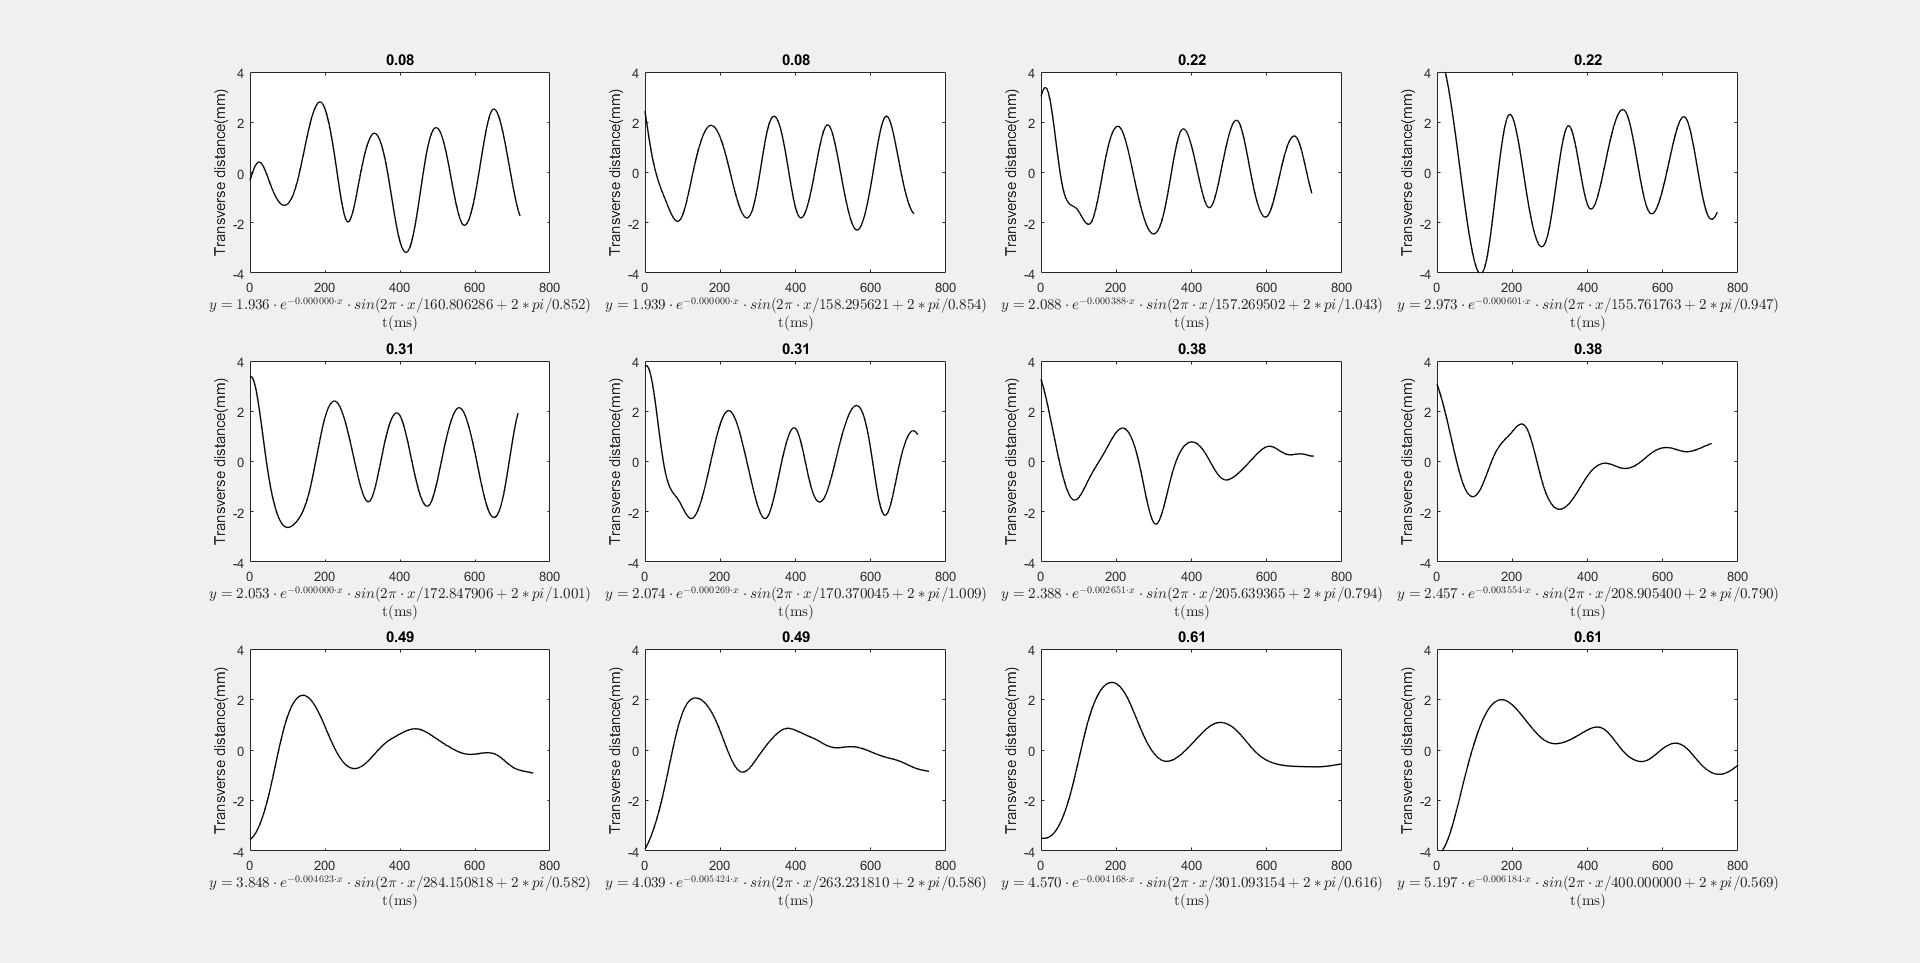

savefig('TransverseSpeedAmplitude10oilTime.fig')


figure('visible','on');
clf;
freq10 = [];
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane; a = Plane(1); b = Plane(2); d = Plane(3);
        x0 = 0; y0 = (d - a * x0) / b;
        x1 = 1; y1 = (d - a * x1) / b;
        vector = [x0,y0;x1,y1];
        for k = 1:length(traj3D)
            q = traj3D(k,1:2);
            p = proj(vector,q);
            traj3D(k,1:2) = p;
        end
        subplot(3,4,i - 12);
        x = traj3D(:,1); x = x - x(1);
        y = traj3D(:,2); y = y - y(1);
        z = traj3D(:,3);
        Tdistance = sqrt(x.^2 + y.^2);
        xNew = sqrt(x.^2 + y.^2);
        for k = 1:length(xNew)
            if x(k) > 0
                xNew(k) = -1 * xNew(k);
            end
        end
        xNew = [xNew,z];
        xTable = array2table(xNew,'VariableNames',{'horizonal','z'});
        writetable(xTable, [FileName{i}, 'Project.csv']);
        for k = 1:length(Tdistance)
            if x(k) > 0
                Tdistance(k) = -1 * Tdistance(k);
            end
        end
       
        MaxID = min(find(z>174));
        MinID = max(find(z<23));
        Tdistance = detrend(Tdistance(MinID:MaxID));
        t = [1:length(z)] * 5;
        t1 = t(MinID:MaxID) - t(MinID);
        
        plot(t1, Tdistance, 'k', 'LineWidth',1);
        
        try
            [fitResult, gof] = createFit(t1, Tdistance)
            fitDistance = fitResult(t1);
%             hold on;
%             plot(t1, fitDistance);
            xlim([0, 800])
            ylim([-4 4])
            result = [fitResult.a,fitResult.b,fitResult.c,fitResult.d];
            ylabel('Transverse distance(mm)');
            title(num2str(foil(i)))
            xlabel({sprintf('$y = %.3f\\cdot e^{%.6f\\cdot x}\\cdot sin(2\\pi\\cdot x / %.6f + 2*pi / %.3f)$', result);'t(ms)' }, 'Interpreter','latex')
        catch
        end
        %title(FileName{i});
    end
end

fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       2.169  (2.03, 2.308)
       b =  -2.303e-14  (fixed at bound)
       c =       165.1  (163.8, 166.3)
       d =      0.6839  (0.6747, 0.6931)
       e =     0.05219  (-0.04555, 0.1499)

gof = struct with fields:
           sse: 52.9928
       rsquare: 0.8714
           dfe: 146
    adjrsquare: 0.8687
          rmse: 0.6025


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       2.149  (2.018, 2.281)
       b =  -2.221e-14  (fixed at bound)
       c =       167.3  (166.2, 168.5)
       d =      0.7967  (0.7842, 0.8091)
       e =     -0.1526  (-0.2466, -0.0586)

gof = struct with fields:
           sse: 60.1506
       rsquare: 0.8538
           dfe: 163
    adjrsquare: 0.8511
          rmse: 0.6075


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       1.857  (1.71, 2.005)
       b =  -4.463e-05  (-0.0002332, 0.000144)
       c =       157.9  (157.2, 158.6)
       d =       1.054  (1.04, 1.067)
       e =    -0.05624  (-0.1067, -0.00583)

gof = struct with fields:
           sse: 13.7159
       rsquare: 0.9612
           dfe: 144
    adjrsquare: 0.9601
          rmse: 0.3086


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       1.615  (1.56, 1.67)
       b =   -2.22e-14  (fixed at bound)
       c =       155.9  (155.3, 156.6)
       d =      0.9568  (0.9469, 0.9666)
       e =    -0.02749  (-0.0663, 0.01132)

gof = struct with fields:
           sse: 7.6775
       rsquare: 0.9686
           dfe: 140
    adjrsquare: 0.9679
          rmse: 0.2342


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       1.819  (1.673, 1.965)
       b =  -9.725e-05  (-0.0002946, 0.0001001)
       c =       159.2  (158.5, 160)
       d =      0.6694  (0.6638, 0.6749)
       e =      0.2578  (0.2074, 0.3082)

gof = struct with fields:
           sse: 13.0482
       rsquare: 0.9515
           dfe: 140
    adjrsquare: 0.9501
          rmse: 0.3053


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       4.272  (3.692, 4.853)
       b =    -0.00452  (-0.005461, -0.003579)
       c =       263.4  (250.9, 275.8)
       d =      0.8248  (0.8042, 0.8454)
       e =    -0.04398  (-0.1743, 0.08632)

gof = struct with fields:
           sse: 87.8263
       rsquare: 0.7025
           dfe: 147
    adjrsquare: 0.6944
          rmse: 0.7730


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       4.038  (3.164, 4.912)
       b =   -0.004964  (-0.006511, -0.003416)
       c =       229.6  (214.6, 244.6)
       d =      0.7989  (0.772, 0.8258)
       e =    -0.07074  (-0.2478, 0.1063)

gof = struct with fields:
           sse: 147.5228
       rsquare: 0.5101
           dfe: 139
    adjrsquare: 0.4960
          rmse: 1.0302


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       2.651  (2.468, 2.833)
       b =  -0.0009297  (-0.001112, -0.0007478)
       c =       184.5  (183.5, 185.6)
       d =      0.6471  (0.6423, 0.6518)
       e =      0.2354  (0.1795, 0.2913)

gof = struct with fields:
           sse: 19.8364
       rsquare: 0.9612
           dfe: 156
    adjrsquare: 0.9602
          rmse: 0.3566


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       2.729  (2.187, 3.272)
       b =  -0.0006135  (-0.001122, -0.0001046)
       c =       183.8  (180.9, 186.8)
       d =      0.6333  (0.6197, 0.647)
       e =    -0.04441  (-0.2235, 0.1347)

gof = struct with fields:
           sse: 186.1476
       rsquare: 0.6504
           dfe: 150
    adjrsquare: 0.6411
          rmse: 1.1140


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =        5.39  (4.792, 5.989)
       b =   -0.005909  (-0.006965, -0.004853)
       c =       305.4  (286.1, 324.7)
       d =       0.869  (0.8468, 0.8913)
       e =     -0.3797  (-0.4962, -0.2631)

gof = struct with fields:
           sse: 90.9529
       rsquare: 0.7875
           dfe: 170
    adjrsquare: 0.7825
          rmse: 0.7314


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       5.623  (5.068, 6.178)
       b =   -0.005358  (-0.006194, -0.004522)
       c =       278.1  (265.6, 290.6)
       d =      0.8713  (0.8528, 0.8899)
       e =     -0.4062  (-0.5177, -0.2947)

gof = struct with fields:
           sse: 85.9128
       rsquare: 0.8024
           dfe: 170
    adjrsquare: 0.7977
          rmse: 0.7109


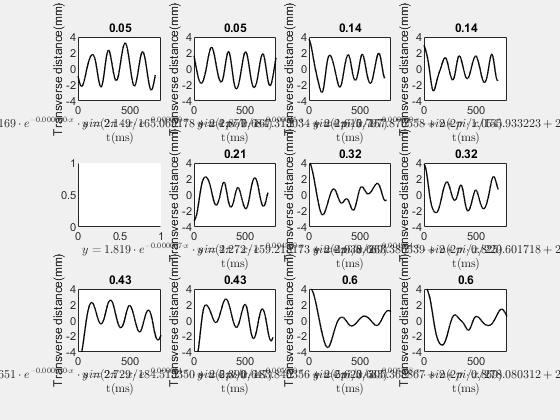

savefig('TransverseSpeedAmplitude100oilTime.fig')

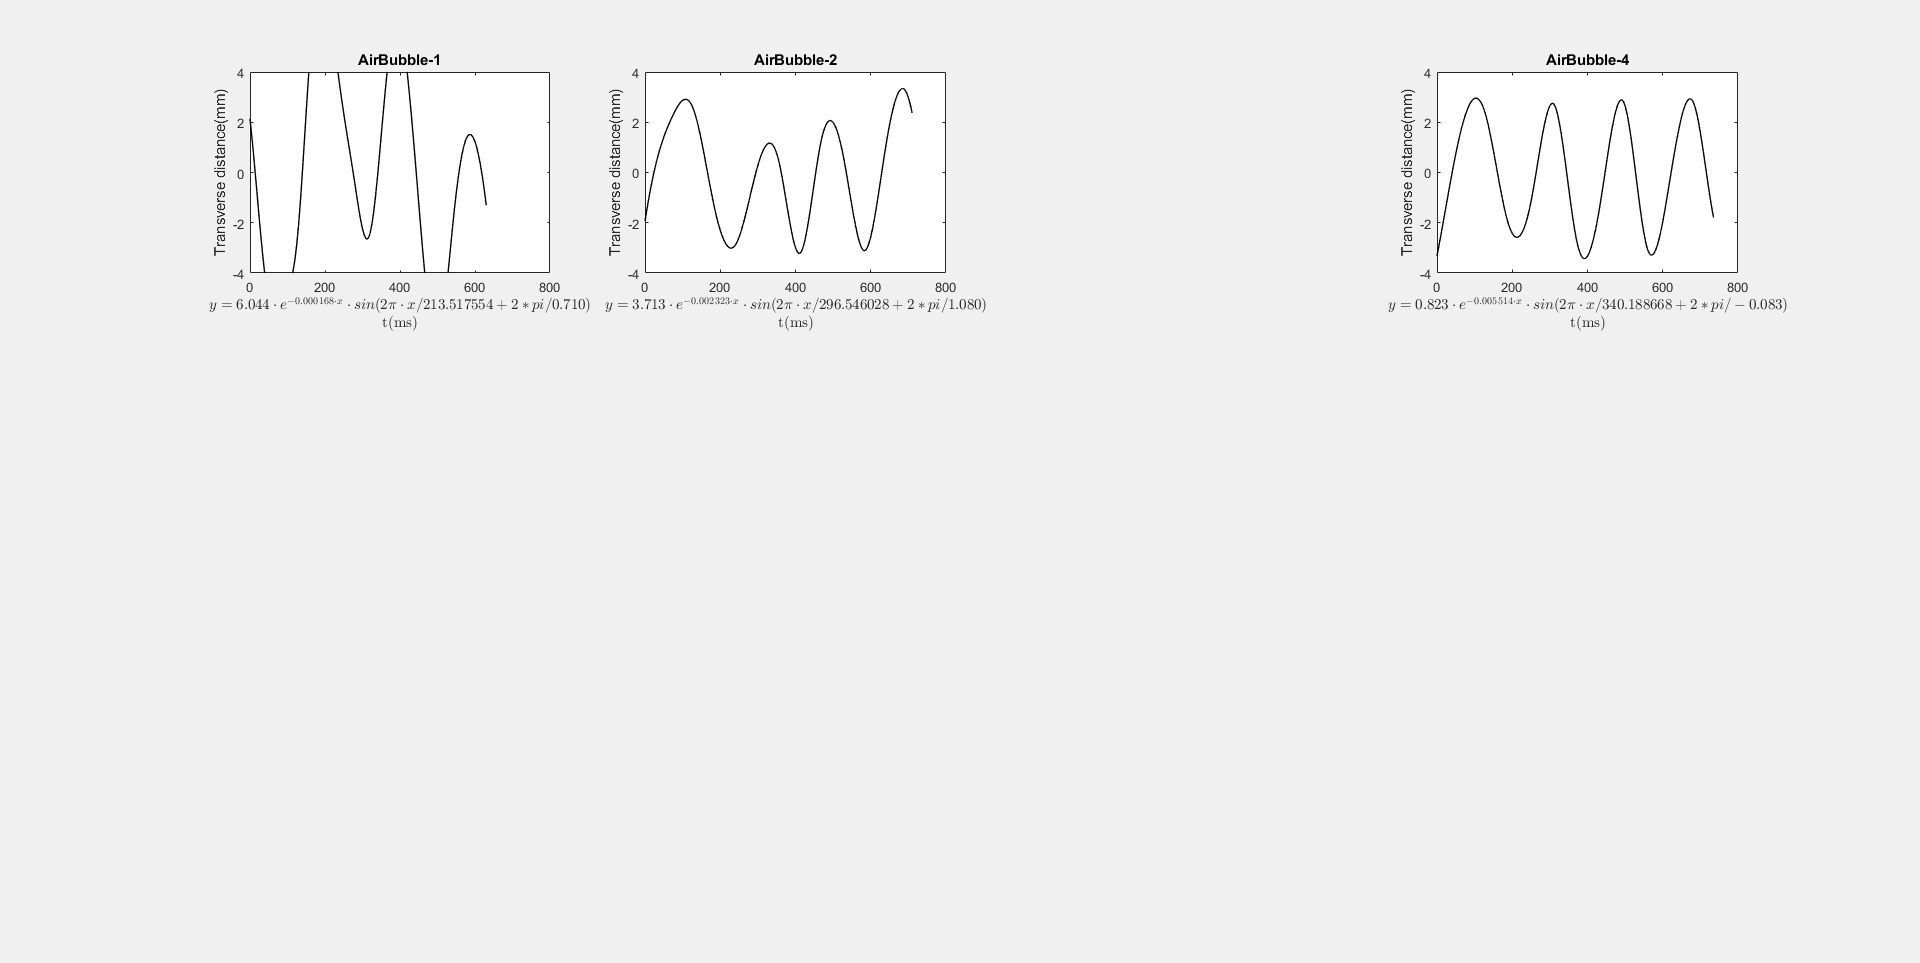

fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       6.044  (4.726, 7.362)
       b =  -0.0001678  (-0.0007612, 0.0004256)
       c =       213.5  (209.2, 217.8)
       d =      0.7099  (0.6939, 0.7258)
       e =     -0.2092  (-0.6542, 0.2359)

gof = struct with fields:
           sse: 728.0436
       rsquare: 0.6406
           dfe: 122
    adjrsquare: 0.6288
          rmse: 2.4429


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =       3.713  (2.385, 5.042)
       b =   -0.002323  (-0.00366, -0.0009849)
       c =       296.5  (279.9, 313.2)
       d =        1.08  (1.028, 1.131)
       e =     -0.1846  (-0.4788, 0.1097)

gof = struct with fields:
           sse: 414.5823
       rsquare: 0.2825
           dfe: 138
    adjrsquare: 0.2617
          rmse: 1.7333


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;
     Coefficients (with 95% confidence bounds):
       a =      0.8229  (-2.091, 3.736)
       b =   -0.005514  (-0.02859, 0.01756)
       c =       340.2  (18.87, 661.5)
       d =    -0.08281  (-0.08492, -0.0807)
       e =    0.001902  (-0.368, 0.3718)

gof = struct with fields:
           sse: 615.5387
       rsquare: 0.0542
           dfe: 143
    adjrsquare: 0.0277
          rmse: 2.0747


figure('visible','on');
clf;
freq10 = [];
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane; a = Plane(1); b = Plane(2); d = Plane(3);
        x0 = 0; y0 = (d - a * x0) / b;
        x1 = 1; y1 = (d - a * x1) / b;
        vector = [x0,y0;x1,y1];
        for k = 1:length(traj3D)
            q = traj3D(k,1:2);
            p = proj(vector,q);
            traj3D(k,1:2) = p;
        end
        subplot(3,4,i - 24);
        x = traj3D(:,1); x = x - x(1);
        y = traj3D(:,2); y = y - y(1);
        z = traj3D(:,3);
        Tdistance = sqrt(x.^2 + y.^2);
        xNew = sqrt(x.^2 + y.^2);
        for k = 1:length(xNew)
            if x(k) > 0
                xNew(k) = -1 * xNew(k);
            end
        end
        xNew = [xNew,z];
        xTable = array2table(xNew,'VariableNames',{'horizonal','z'});
        writetable(xTable, [FileName{i}, 'Project.csv']);
        for k = 1:length(Tdistance)
            if x(k) > 0
                Tdistance(k) = -1 * Tdistance(k);
            end
        end
       
        MaxID = min(find(z>174));
        MinID = max(find(z<23));
        Tdistance = detrend(Tdistance(MinID:MaxID));
        t = [1:length(z)] * 5;
        t1 = t(MinID:MaxID) - t(MinID);
        
        plot(t1, Tdistance,'k', 'LineWidth',1);
        
        try
            [fitResult, gof] = createFit(t1, Tdistance)
            fitDistance = fitResult(t1);
%             hold on;
%             plot(t1, fitDistance);
            xlim([0, 800])
            ylim([-4 4])
            result = [fitResult.a,fitResult.b,fitResult.c,fitResult.d];
            ylabel('Transverse distance(mm)');
            xlabel({sprintf('$y = %.3f\\cdot e^{%.6f\\cdot x}\\cdot sin(2\\pi\\cdot x / %.6f + 2*pi / %.3f)$', result);'t(ms)' }, 'Interpreter','latex')
        catch
        end
        title(FileName{i});
    end
end

figure('visible','on');
clf;
freq10 = [];
for i = 29:35
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane; a = Plane(1); b = Plane(2); d = Plane(3);
        x0 = 0; y0 = (d - a * x0) / b;
        x1 = 1; y1 = (d - a * x1) / b;
        vector = [x0,y0;x1,y1];
        for k = 1:length(traj3D)
            q = traj3D(k,1:2);
            p = proj(vector,q);
            traj3D(k,1:2) = p;
        end
        subplot(3,3,i - 28);
        x = traj3D(:,1); x = x - x(1);
        y = traj3D(:,2); y = y - y(1);
        z = traj3D(:,3);
        Tdistance = sqrt(x.^2 + y.^2);
        xNew = sqrt(x.^2 + y.^2);
        for k = 1:length(xNew)
            if x(k) > 0
                xNew(k) = -1 * xNew(k);
            end
        end
        xNew = [xNew,z];
        xTable = array2table(xNew,'VariableNames',{'horizonal','z'});
        writetable(xTable, [FileName{i}, 'Project.csv']);
        for k = 1:length(Tdistance)
            if x(k) > 0
                Tdistance(k) = -1 * Tdistance(k);
            end
        end
       
        MaxID = min(find(z>174));
        MinID = max(find(z<23));
        Tdistance = detrend(Tdistance(MinID:MaxID));
        t = [1:length(z)] * 5;
        t1 = t(MinID:MaxID) - t(MinID);
        
        plot(t1, Tdistance);
        
        try
            [fitResult, gof] = createFit(t1, Tdistance)
            fitDistance = fitResult(t1);
            hold on;
            plot(t1, fitDistance);
            result = [fitResult.a,fitResult.b,fitResult.c,fitResult.d];
            ylabel('Transverse distance(mm)');
            xlabel({sprintf('$y = %.3f\\cdot e^{%.6f\\cdot x}\\cdot sin(2\\pi\\cdot x / %.6f + 2*pi / %.3f)$', result);'t(ms)' }, 'Interpreter','latex')
        catch
        end
        title(FileName{i});
    end
end

Undefined variable FileName.

savefig('TransverseSpeedAmplitudeSevenMoreCaseTime.fig')

function [ProjPoint] = proj(vector, q)
    p0 = vector(1,:);
    p1 = vector(2,:);
    a = [-q(1)*(p1(1)-p0(1)) - q(2)*(p1(2)-p0(2)); ...
        -p0(2)*(p1(1)-p0(1)) + p0(1)*(p1(2)-p0(2))]; 
    b = [p1(1) - p0(1), p1(2) - p0(2);...
        p0(2) - p1(2), p1(1) - p0(1)];
    ProjPoint = -(b\a);
end
function [f, P1] = findAmplitude(X, Fs)
    L = length(X);
    Y = fft(X);
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(L/2))/L;
end
function result = fitDamping(x,y)
    y = detrend(y);                                                                 % Remove Linear Trend
    yu = max(y);
    yl = min(y);
    yr = (yu-yl);                                                                   % Range of ‘y’
    yz = y-yu+(yr/2);
    zci = @(v) find(v(:).*circshift(v(:), [-1 0]) <= 0);                            % Returns Approximate Zero-Crossing Indices Of Argument Vector
    zt = x(zci(y));
    per = 2*mean(diff(zt));                                                         % Estimate period
    ym = mean(y);                                                                   % Estimate offset
    fit = @(b,x)  b(1) .* exp(b(2).*x) .* (sin(2*pi*x./b(3) + 2*pi/b(4))) + b(5);        % Objective Function to fit
    fcn = @(b) norm(fit(b,x) - y);    
    options = optimset('MaxFunEvals',50000, 'MaxIter', 500*500); % Least-Squares cost function
    %[result,nmrs] = fminsearch(fcn, [yr; -0.5;  per;  -1;  ym], options);
    [result,nmrs] = fminsearch(fcn, [yr; -0.5;  per;  -1;  ym], options);
end
function [fitresult, gof] = createFit(t1, Tdistance)
    %CREATEFIT(T1,TDISTANCE)
    %  Create a fit.
    %
    %  Data for 'untitled fit 1' fit:
    %      X Input : t1
    %      Y Output: Tdistance
    %  Output:
    %      fitresult : a fit object representing the fit.
    %      gof : structure with goodness-of fit info.
    %
    %  See also FIT, CFIT, SFIT.
    
    %  Auto-generated by MATLAB on 06-Nov-2020 14:17:37
    
    
    %% Fit: 'untitled fit 1'.
    [xData, yData] = prepareCurveData( t1, Tdistance );
    
    % Set up fittype and options.
    ft = fittype( 'a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e;', 'independent', 'x', 'dependent', 'y' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.DiffMinChange = 1e-11;
    opts.Display = 'Off';
    opts.Lower = [0 -0.09 0 -Inf -Inf];
    opts.MaxFunEvals = 60000;
    opts.MaxIter = 40000;
    opts.Robust = 'LAR';
    opts.StartPoint = [8 -0.007 200 0.823457828327293 0.694828622975817];
    opts.TolFun = 1e-11;
    opts.TolX = 1e-11;
    opts.Upper = [10 0 400 Inf Inf];
    
    % Fit model to data.
    [fitresult, gof] = fit( xData, yData, ft, opts );
    
%     % Plot fit with data.
%     figure( 'Name', 'untitled fit 1' );
%     h = plot( fitresult, xData, yData );
%     legend( h, 'Tdistance vs. t1', 'untitled fit 1', 'Location', 'NorthEast', 'Interpreter', 'none' );
%     % Label axes
%     xlabel( 't1', 'Interpreter', 'none' );
%     ylabel( 'Tdistance', 'Interpreter', 'none' );
%     grid on
end